clc 
clear

currentwd = pwd

% 1
close('all');    % Close all figures so we start with a clean slate

% read images and convert to single format
set1_far = im2double(imread('./derek.jpg')); 		        % "far" picture
set1_near = im2double(imread('./nutmeg.jpg')); 	    		% "near" picture
% (Optional) convert to grayscale
%set1_far = rgb2gray(set1_far)
%set1_near = rgb2gray(set1_near);


% Uncomment the call to get_points_interactively() to set the corresponding
% points in the two images to establish alignment (e.g., by the eyes).
% The function performs translation, rotation and scaling to align those 
% two points in the two images.
%[x1, y1, x2, y2] = get_points_interactively(set1_near, set1_far);
x1 = [605.1403 758.9682]; y1 = [287.3709 360.6136];
x2 = [303.8974 442.5175]; y2 = [348.1681 332.5175];
[set1_near_aligned, set1_far_aligned] = align_images(set1_near, set1_far, x1, y1, x2, y2);


%% Choose the cutoff frequencies for the low-pass and high-pass filters
cutoff_low  = 15.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!
cutoff_high = 10.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!

%% Compute the hybrid image (you supply this code)

set1_hybrid = hybridImage(set1_far_aligned, set1_near_aligned, cutoff_low, cutoff_high);

%% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
%fig=figure; hold off, imagesc(set1_hybrid), axis image;
%figure(fig)
%[x, y] = ginput(2);  x = round(x); y = round(y);
%close(fig);
% Once you these coordinates, uncomment the lines above, and 
% hard code the values below.
x = [354 1453]; y = [206 1077];
set1_hybrid = set1_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set1_hybrid);
viewed_from_afar = padarray(set1_hybrid, max(h, w));
figure; montage({set1_near, set1_far, set1_hybrid, viewed_from_afar}, 'Size', [2,2]);

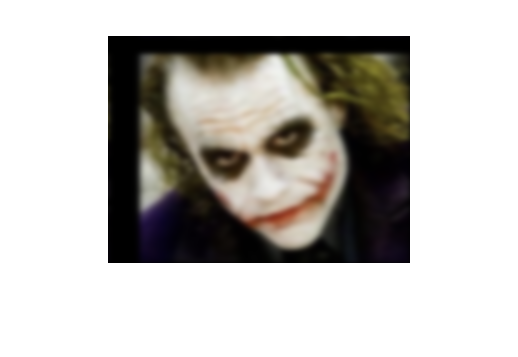

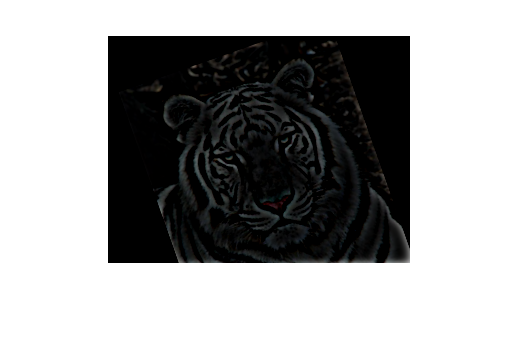

% 2
set2_far = im2double(imread('joker.jpg')); 		        % "far" picture
set2_near = im2double(imread('whitetiger.png')); 	    		        % "near" picture
%set2_near = imresize(set2_near, size(set2_far,2)/ size(set2_near,2));
% (Optional) convert images to grayscale
% set2_far = rgb2gray(set2_far);                
% set2_near = rgb2gray(set2_near);

% Interactively get two pairs of points from each image to establish
% alignment.
% [x1, y1, x2, y2] = get_points_interactively(set2_near, set2_far);
x1 = [119.4344 206.8980]; y1 = [144.5233 145.6895];
x2 = [90.3963 147.6313]; y2 = [105.0000 85.7143];
[set2_near_aligned, set2_far_aligned] = align_images(set2_near, set2_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 15.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 10.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)

% Compute the hybrid image (you supply this code)
set2_hybrid = hybridImage(set2_far_aligned, set2_near_aligned, cutoff_low, cutoff_high);

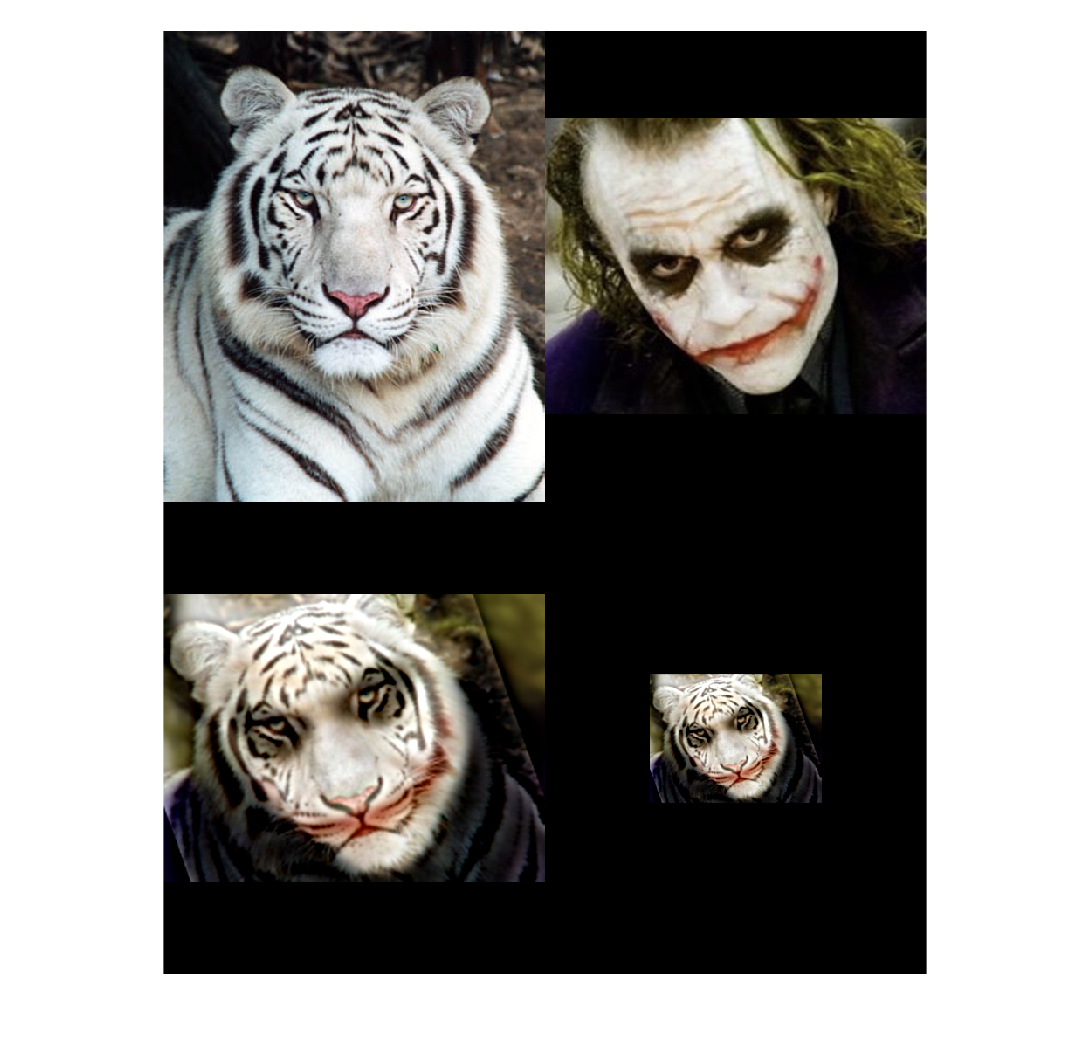


% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
% disp('input crop points (two opposite corners)');
% fig=figure; hold off, imagesc(set2_hybrid), axis image;
% figure(fig)
% [x, y] = ginput(2);  x = round(x); y = round(y);
% close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [52 286]; y = [42 218];
set2_hybrid = set2_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set2_hybrid);
viewed_from_afar = padarray(set2_hybrid, max(h, w));
figure; montage({set2_near, set2_far, set2_hybrid, viewed_from_afar}, 'Size', [2,2]);

% 3
set3_far = im2double(imread('wsc.jpg')); 		        % "far" picture
set3_near = im2double(imread('lion.jpeg')); 	    		        % "near" picture
%set2_near = imresize(set2_near, size(set2_far,2)/ size(set2_near,2));
% (Optional) convert images to grayscale
set3_far = rgb2gray(set3_far);                
set3_near = rgb2gray(set3_near);
figure;imshow(set3_far);

% Interactively get two pairs of points from each image to establish
% alignment.
% [x1, y1, x2, y2] = get_points_interactively(set3_near, set3_far);
x1 = [220.5023 280.3088]; y1 = [151.3894 149.9654];
x2 = [546.0175 693.2187]; y2 = [543.8455 561.1633];
[set3_near_aligned, set3_far_aligned] = align_images(set3_near, set3_far, x1, y1, x2, y2);

% Choose the cutoff frequencies for the low-pass and high-pass filters
% CHOOSE CAREFULLY!  Values will depend on the images used!
cutoff_low  = 20.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian)
cutoff_high = 10.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian)

% Compute the hybrid image (you supply this code)
set3_hybrid = hybridImage(set3_far_aligned, set3_near_aligned, cutoff_low, cutoff_high);

% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
% disp('input crop points (two opposite corners)');
% fig=figure; hold off, imagesc(set3_hybrid), axis image;
% figure(fig)
% [x, y] = ginput(2);  x = round(x); y = round(y);
% close(fig);
% Once you have these coordinates, comment the lines above, and 
% hard code the values below.
x = [30 430]; y = [131 546];
set3_hybrid = set3_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set3_hybrid);
viewed_from_afar = padarray(set3_hybrid, max(h, w));
figure; montage({set3_near, set3_far, set3_hybrid, viewed_from_afar}, 'Size', [2,2]);

% 4

% read images and convert to single format
set4_far = im2double(imread('./lisa.jpeg')); 		        % "far" picture
set4_near = im2double(imread('./skrik.jpeg')); 	    		% "near" picture
% (Optional) convert to grayscale
%set1_far = rgb2gray(set1_far)
%set1_near = rgb2gray(set1_near);


% Uncomment the call to get_points_interactively() to set the corresponding
% points in the two images to establish alignment (e.g., by the eyes).
% The function performs translation, rotation and scaling to align those 
% two points in the two images.
% [x1, y1, x2, y2] = get_points_interactively(set4_near, set4_far);
x1 = [287.672 278.9257]; y1 = [262.1618 230.0918];
x2 = [91.1195 81.2274]; y2 = [57.9504 29.035];
[set4_near_aligned, set4_far_aligned] = align_images(set4_near, set4_far, x1, y1, x2, y2);


%% Choose the cutoff frequencies for the low-pass and high-pass filters
cutoff_low  = 20.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!
cutoff_high = 10.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!

%% Compute the hybrid image (you supply this code)

set4_hybrid = hybridImage(set4_far_aligned, set4_near_aligned, cutoff_low, cutoff_high);

%% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
% fig=figure; hold off, imagesc(set4_hybrid), axis image;
% figure(fig)
% [x, y] = ginput(2);  x = round(x); y = round(y);
% close(fig);
% Once you these coordinates, uncomment the lines above, and 
% hard code the values below.
x = [13 190]; y = [176 426];
set4_hybrid = set4_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set4_hybrid);
viewed_from_afar = padarray(set4_hybrid, max(h, w));
figure; montage({set4_near, set4_far, set4_hybrid, viewed_from_afar}, 'Size', [2,2]);

disp(x1+" "+y1+" "+x2+" "+y2);
disp(x)
disp(y)

% 5

% read images and convert to single format
set5_far = im2double(imread('./portrait.jpeg')); 		        % "far" picture
set5_near = im2double(imread('./pearlgirl.jpeg')); 	    		% "near" picture
% (Optional) convert to grayscale
%set1_far = rgb2gray(set1_far)
%set1_near = rgb2gray(set1_near);


% Uncomment the call to get_points_interactively() to set the corresponding
% points in the two images to establish alignment (e.g., by the eyes).
% The function performs translation, rotation and scaling to align those 
% two points in the two images.
% [x1, y1, x2, y2] = get_points_interactively(set5_near, set5_far);
x1 = [268.7028 300.0392]; y1 = [263.3134 405.2488];
x2 = [243.9840 296.4621]; y2 = [337.6720 505.6020];
[set5_near_aligned, set5_far_aligned] = align_images(set5_near, set5_far, x1, y1, x2, y2);

figure;imshow(set5_near_aligned);
%% Choose the cutoff frequencies for the low-pass and high-pass filters
cutoff_low  = 25.0;   % provide a value for the low-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!
cutoff_high = 5.0;   % provide a value for the high-pass filter cutoff frequency (sigma of gaussian).  CHOOSE CAREFULLY!

%% Compute the hybrid image (you supply this code)

set5_hybrid = hybridImage(set5_far_aligned, set5_near_aligned, cutoff_low, cutoff_high);

%% Crop resulting image:  Crop the result to get rid of any unsightly borders areas.
%disp('input crop points (two opposite corners)');
% fig=figure; hold off, imagesc(set5_hybrid), axis image;
% figure(fig)
% [x, y] = ginput(2);  x = round(x); y = round(y);
% close(fig);
% Once you these coordinates, uncomment the lines above, and 
% hard code the values below.
x = [150 718]; y = [35 724];
set5_hybrid = set5_hybrid(min(y):max(y), min(x):max(x), :);

% Let us try to "simulate" what the hybrid image will look like
% when viewed from afar.  Let us pad a black border around it
% so it effectively shrinks in size when displayed in a montage.
[h, w, ~] = size(set5_hybrid);
viewed_from_afar = padarray(set5_hybrid, max(h, w));
figure; montage({set5_near, set5_far, set5_hybrid, viewed_from_afar}, 'Size', [2,2]);

function im12 = hybridImage(im1, im2, cutoff_low, cutoff_high)
    % FILL IN YOUR CODE HERE
    
    low_fft = fftshift(fft2(im1));
    high_fft = fftshift(fft2(im2));
    
    
    
    h1 = fspecial('gaussian', [size(low_fft,1) size(low_fft,2)], cutoff_low);
    h2 = fspecial('gaussian', [size(high_fft,1) size(high_fft,2)], cutoff_high);
    
    h1 = h1./max(h1,[],'all');
    h1 = repmat(h1,[1 1 size(im1, 3)]);
    
    h2 = h2./max(h2,[],'all');
    h2 = repmat(h2,[1 1 size(im2, 3)]);
    %disp(max(h, [], 'all'));

    low_fft_filtered = low_fft.*h1;
    figure;imshow(real(ifft2(ifftshift(low_fft_filtered))));
    high_fft_filtered = high_fft.*(1-h2);
    figure;imshow(real(ifft2(ifftshift(high_fft_filtered))));
    total_fft = low_fft_filtered+high_fft_filtered;
    %figure;imagesc(log(abs(total_fft(:,:,1))));
    

    total_shift_i = ifft2(ifftshift(total_fft));
    im12 = real(total_shift_i);

    
    
    
    
end

function [x1, y1, x2, y2] = get_points_interactively(im1, im2)
    % displays image and gets two points from the user
    fig=figure; hold off, imagesc(im1), axis image;
    disp('Select two points from each image define rotation, scale, translation')
    figure(fig)
    [x1, y1] = ginput(2);
    figure(fig); hold off, imagesc(im2), axis image;
    figure(fig)
    [x2, y2] = ginput(2);
    close(fig);
end

function [im1, im2] = align_images(im1, im2, x1, y1, x2, y2)
    % Aligns im1 and im2 (translation, scale, rotation) after getting two pairs
    % of points from the user.  In the output of im1 and im2, the two pairs of
    % points will have approximately the same coordinates.
    
    % get image sizes
    [h1, w1, ~] = size(im1);
    [h2, w2, ~] = size(im2);
    
    cx1 = mean(x1); cy1 = mean(y1);
    cx2 = mean(x2); cy2 = mean(y2);
    
    % translate first so that center of ref points is center of image
    tx = round((w1/2-cx1)*2);
    if tx > 0,  im1 = padarray(im1, [0 tx], 'pre');
    else        im1 = padarray(im1, [0 -tx], 'post');
    end
    ty = round((h1/2-cy1)*2);
    if ty > 0,  im1 = padarray(im1, [ty 0], 'pre');
    else        im1 = padarray(im1, [-ty 0], 'post');
    end  
    tx = round((w2/2-cx2)*2) ;
    if tx > 0,  im2 = padarray(im2, [0 tx], 'pre');
    else        im2 = padarray(im2, [0 -tx], 'post');
    end
    ty = round((h2/2-cy2)*2);
    if ty > 0,  im2 = padarray(im2, [ty 0], 'pre');
    else        im2 = padarray(im2, [-ty 0], 'post');
    end
    
    % downscale larger image so that lengths between ref points are the same
    len1 = sqrt((y1(2)-y1(1)).^2+(x1(2)-x1(1)).^2);
    len2 = sqrt((y2(2)-y2(1)).^2+(x2(2)-x2(1)).^2);
    dscale = len2 ./ len1;
    if dscale < 1
        im1 = imresize(im1, dscale, 'bilinear'); 
    else
        im2 = imresize(im2, 1./dscale, 'bilinear');
    end
    
    % rotate im1 so that angle between points is the same
    theta1 = atan2(-(y1(2)-y1(1)), x1(2)-x1(1)); % in matlab, y==1 is at the top of the N x M image, and y==N is at the bottom
    theta2 = atan2(-(y2(2)-y2(1)), x2(2)-x2(1));
    dtheta = theta2-theta1;
    im1 = imrotate(im1, dtheta*180/pi, 'bilinear'); % imrotate uses degree units
    
    % Crop images (on both sides of border) to be same height and width
    [h1, w1, ~] = size(im1);
    [h2, w2, ~] = size(im2);
    
    minw = min(w1, w2);
    brd = (max(w1, w2)-minw)/2;
    if minw == w1 % crop w2
        im2 = im2(:, (ceil(brd)+1):end-floor(brd), :);
        tx = tx-ceil(brd);
    else
        im1 = im1(:, (ceil(brd)+1):end-floor(brd), :);
        tx = tx+ceil(brd);    
    end
    
    minh = min(h1, h2);
    brd = (max(h1, h2)-minh)/2;
    if minh == h1 % crop w2
        im2 = im2((ceil(brd)+1):end-floor(brd), :, :);
        ty = ty-ceil(brd);
    else
        im1 = im1((ceil(brd)+1):end-floor(brd), :, :);
        ty = ty+ceil(brd);    
    end    
end